## Deblurring Images Using the Blind Deconvolution Algorithm

%%盲反卷积算法复原图像
% The Blind Deconvolution Algorithm can be used effectively when no
% information about the distortion (blurring and noise) is known. The
% algorithm restores the image and the point-spread function (PSF)
% simultaneously. The accelerated, damped Richardson-Lucy algorithm is used
% in each iteration. Additional optical system (e.g. camera)
% characteristics can be used as input parameters that could help to
% improve the quality of the image restoration. PSF constraints can be
% passed in through a user-specified function
%在不知道图像失真信息(模糊和噪声)信息情况下，盲反卷积算法可以有效地加以利用。该算法
%对图像和点扩展函数（PSF）的同时进行复原。每次迭代都使用加速收敛Richardson-Lucy 
%算法。额外的光学系统（如照相机）的特性可作为输入参数，帮助改善图像复原质量。可以通
%过用户指定的函数对PSF进行限制

## Step 1: Read Image

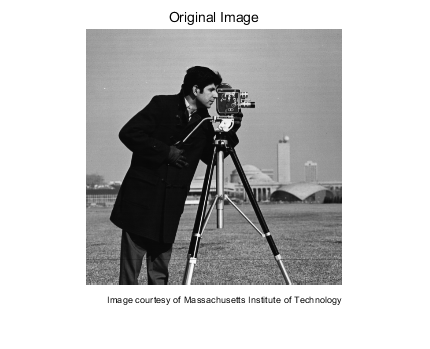

%%第一步：读取图像
% The example reads in an intensity image. The |deconvblind| function can
% handle arrays of any dimension.
%该示例读取一个灰度图像。| deconvblind |函数可以处理任何维数组。
clc;clear;close all
I = imread('cameraman.tif');
figure;imshow(I);title('Original Image');
text(size(I,2),size(I,1)+15, ...
    'Image courtesy of Massachusetts Institute of Technology', ...
'FontSize',7,'HorizontalAlignment','right');

## Step 2: Simulate a Blur

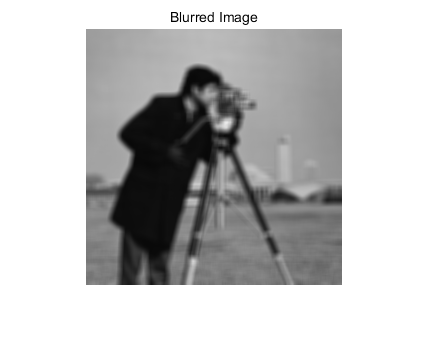

%%第二步：模拟一个模糊
% Simulate a real-life image that could be blurred (e.g., due to camera
% motion or lack of focus). The example simulates the blur by convolving a
% Gaussian filter with the true image (using |imfilter|). The Gaussian filter
% then represents a point-spread function, |PSF|.
 %模拟一个现实中存在的模糊图像（例如，由于相机抖动或对焦不足）。这个例子通过对真实
%图像进行高斯滤波器模拟图像模糊（使用|imfilter|）。高斯滤波器是一个点扩展函数，
%|PSF|。
PSF=fspecial('gaussian',7,10);
Blurred=imfilter(I,PSF,'symmetric','conv');  %对图像I进行滤波处理；
figure;imshow(Blurred);title('Blurred Image');

## Step 3: Restore the Blurred Image Using PSFs of Various Sizes

%%第三步：使用不同的点扩展函数复原模糊图像
% To illustrate the importance of knowing the size of the true PSF, this
% example performs three restorations. Each time the PSF reconstruction
% starts from a uniform array--an array of ones.
%为了说明知道真实PSF的大小的重要性，这个例子执行三个修复。PSF函数重建每次都是从统一
%的全一数组开始。

The first restoration, `J1` and `P1`, uses an undersized array, `UNDERPSF`, for an initial guess of the PSF. The size of the UNDERPSF array is 4 pixels shorter in each dimension than the true PSF. 

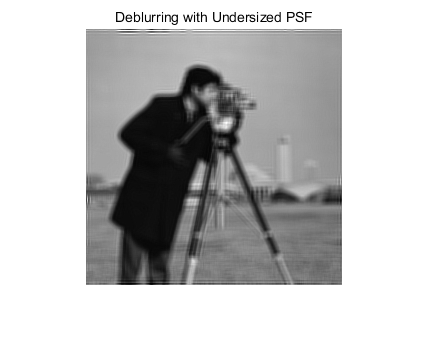

%第一次复原，|J1|和|P1|，使用一个较小数组，| UNDERPSF |，来对PSF的初步猜测。该
%UNDERPSF数组每维比真实PSF少4个元素。
UNDERPSF = ones(size(PSF)-4);
[J1 P1] = deconvblind(Blurred,UNDERPSF);
figure;imshow(J1);title('Deblurring with Undersized PSF');

The second restoration, `J2` and `P2`, uses an array of ones, `OVERPSF`, for an initial PSF that is 4 pixels longer in each dimension than the true PSF.

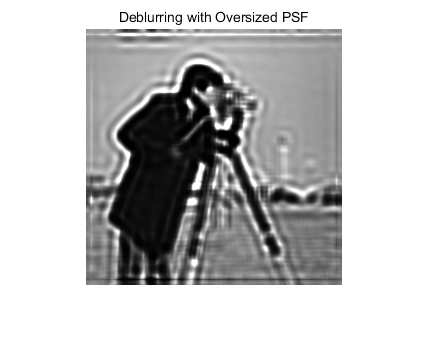

%第二次复原，|J2|和|P2|，使用一个元素全为1的数组，| OVERPSF|，初始PSF每维比真
%实PSF多4个元素。
OVERPSF = padarray(UNDERPSF,[4 4],'replicate','both');
[J2 P2] = deconvblind(Blurred,OVERPSF);
figure;imshow(J2);title('Deblurring with Oversized PSF');

The third restoration, `J3` and `P3`, uses an array of ones, `INITPSF`, for an initial PSF that is exactly of the same size as the true PSF.

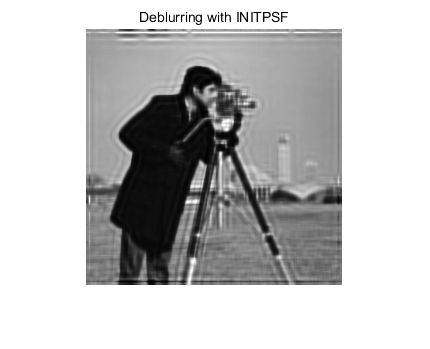

%第三次复原，|J3|和|P3|，使用一个全为一的数组| INITPSF |作为初次PSF，每维与真正
%的PSF相同。
INITPSF = padarray(UNDERPSF,[2 2],'replicate','both');
[J3 P3] = deconvblind(Blurred,INITPSF);
figure;imshow(J3);title('Deblurring with INITPSF');

## Step 4: Analyzing the Restored PSF

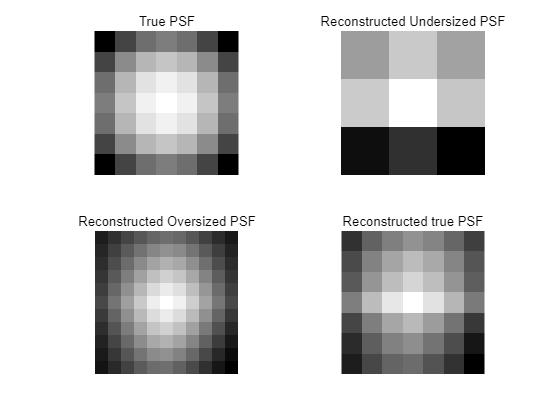

%%第四步：分析复原函数PSF
% All three restorations also produce a PSF. The following pictures show
% how the analysis of the reconstructed PSF might help in guessing the
% right size for the initial PSF. In the true PSF, a Gaussian filter, the
% maximum values are at the center (white) and diminish at the borders (black).
%所有这三个复原也产生PSF。以下图片显示对PSF重建分析的如何可能有助于猜测最初PSF的大
%小。在真正的PSF中，高斯滤波器的最高值在中心（白），到边界消失（黑）。
figure;
subplot(221);imshow(PSF,[],'InitialMagnification','fit');
title('True PSF');
subplot(222);imshow(P1,[],'InitialMagnification','fit');
title('Reconstructed Undersized PSF');
subplot(223);imshow(P2,[],'InitialMagnification','fit');
title('Reconstructed Oversized PSF');
subplot(224);imshow(P3,[],'InitialMagnification','fit');
title('Reconstructed true PSF');

The PSF reconstructed in the first restoration, `P1`, obviously does not fit into the constrained size. It has a strong signal variation at the borders. The corresponding image, `J1`, does not show any improved clarity vs. the blurred image,.

 %第一次复原的PSF，|P1|，显然不适合大小的限制。它在边界有一个强烈的变化信号。
%相应的图片|J1|，与模糊图像|Blurred|比没有表现出清晰度提高。

The PSF reconstructed in the second restoration, `P2`, becomes very smooth at the edges. This implies that the restoration can handle a PSF of a smaller size. The corresponding image, `J2`, shows some deblurring but it is strongly corrupted by the ringing.

 %第二次复原的PSF，|P2|，边缘变得非常平滑。这意味着复原可以处理一个更细致的
%PSF。相应的图片|J2|，显得清晰了，但被一些“振铃”强烈破坏。

Finally, the PSF reconstructed in the third restoration, `P3`, is somewhat intermediate between `P1` and `P2`. The array, `P3`, resembles the true PSF very well. The corresponding image, `J3`, shows significant improvement; however it is still corrupted by the ringing.

 %最后，第三次复原的PSF，|P3|，介于|P1|和|P2|之间。该阵列|P3|，非常接近真
%正的PSF。相应的图片，|J3|，显示了显着改善，但它仍然被一些“振铃”破坏。

## Step 5: Improving the Restoration

%%第五步：改善图像复原
% The ringing in the restored image, |J3|, occurs along the areas of sharp
% intensity contrast in the image and along the image borders. This example
% shows how to reduce the ringing effect by specifying a weighting
% function. The algorithm weights each pixel according to the |WEIGHT| array
% while restoring the image and the PSF. In our example, we start by
% finding the "sharp" pixels using the edge function. By trial and error,
% we determine that a desirable threshold level is 0.3.
%在复原图像|J3|内部灰度对比鲜明的地方和图像边界都出现了“振铃”。这个例子说明了如何
%通过定义一个加权函数来减少图像中的“振铃”。该算法是在对图像和PSF进行复原时，对每个
%像元根据|WEIGHT|数组进行加权计算。在我们的例子，我们从用边缘函数查找“鲜明”像元
%开始。通过反复试验，我们确定理想的阈值为0.3。
WEIGHT = edge(I,'sobel',.3);

To widen the area, we use `imdilate` and pass in a structuring element, `se`.

%为了拓宽领域，我们使用|imdilate|并传递一个结构元素|se|。
se = strel('disk',2);
WEIGHT = 1-double(imdilate(WEIGHT,se));

The pixels close to the borders are also assigned the value 0.

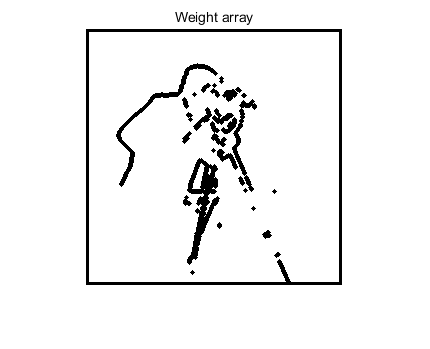

%在边界附近像素的值也被分配为0。
WEIGHT([1:3 end-[0:2]],:) = 0;
WEIGHT(:,[1:3 end-[0:2]]) = 0;
figure;imshow(WEIGHT);title('Weight array');

The image is restored by calling deconvblind with the `WEIGHT` array and an increased number of iterations (30). Almost all the ringing is suppressed.

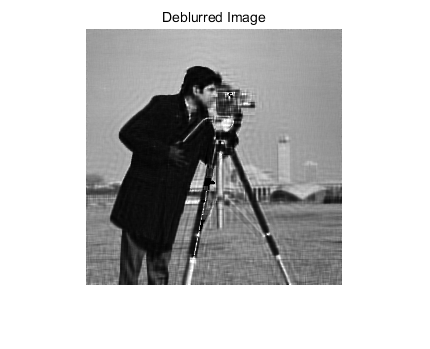

%该图像通过|WEIGHT|数组和增加重复次数（30）调用deconvblind函数来复原。几乎所
%有的“振铃”被抑制。
[J P] = deconvblind(Blurred,INITPSF,30,[],WEIGHT);
figure;imshow(J);title('Deblurred Image');

## Step 6: Using Additional Constraints on the PSF Restoration

%第六步：使用附加约束对PSF复原
% The example shows how you can specify additional constraints on the PSF.
%这个例子说明了如何在PSF上指定额外的限制。
% The function, |FUN|, below returns a modified PSF array which deconvblind
% uses for the next iteration. 
%函数|FUN|返还一个修改了的PSF数组，用作deconvblind函数的下一次重复。
% In this example, |FUN| modifies the PSF by cropping it by |P1| and |P2| number
% of pixels in each dimension, and then padding the array back to its
% original size with zeros. This operation does not change the values in
% the center of the PSF, but effectively reduces the PSF size by |2*P1| and
% |2*P2| pixels. 
%在这个例子中，通过对PSF数组各维数剪切|P1|和|P2|个值实现对PSF的修改，对数组填充
%回零。此操作不会改变在PSF中心的值，而且有效地在各维减少了|2*P1|和| 2*P2|元
%素。
 
P1 = 2;
P2 = 2;
FUN = @(PSF) padarray(PSF(P1+1:end-P1,P2+1:end-P2),[P1 P2]);

The anonymous function, `FUN`, is passed into `deconvblind` last.

%该匿名函数|FUN|，最后传递给| deconvblind |。

In this example, the size of the initial PSF, `OVERPSF`, is 4 pixels larger than the true PSF. Setting P1=2 and P2=2 as parameters in `FUN` effectively makes the valuable space in `OVERPSF` the same size as the true PSF. Therefore, the outcome, `JF` and `PF`, is similar to the result of deconvolution with the right sized PSF and no `FUN` call, `J` and `P`, from step 4.

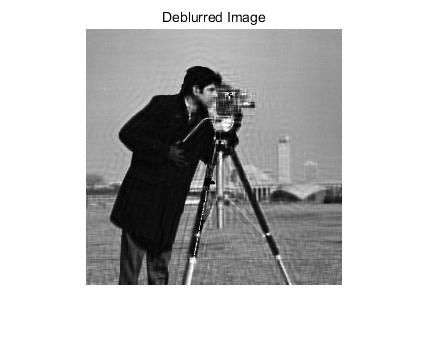

%在这个例子中，初始PSF，|OVERPSF|，每维比真正的PSF多4个像素，。设置P1=2和P2=2作
%为|FUN|的参数，可有效地使|OVERPSF|与真正的PSF的大小相同。因此，得到的结果|JF|
%和|PF|，与第四步不使用|FUN|而仅用正确尺寸PSF盲反卷积得到的结果|J|和|P|类似。
[JF PF] = deconvblind(Blurred,OVERPSF,30,[],WEIGHT,FUN);
figure;imshow(JF);title('Deblurred Image');

If we had used the oversized initial PSF, `OVERPSF`, without the constraining function, `FUN`, the resulting image would be similar to the unsatisfactory result, `J2`, achieved in Step 3.

Note, that any unspecified parameters before `FUN` can be omitted, such as `DAMPAR` and `READOUT` in this example, without requiring a place holder, ([]).

 %如果我们使用了没有约束的函数|FUN|的较大的初始PSF，| OVERPSF |，所得图像将类
%似第3步得到的效果并不理想的|J2|。 
%注意，任何在|FUN|之前未指定参数都可以省略，如|DAMPAR|和|READOUT|在这个例子中，而不需要指示他们的位置，([])。

*Copyright 2004-2005 The MathWorks, Inc.*